# Report 4

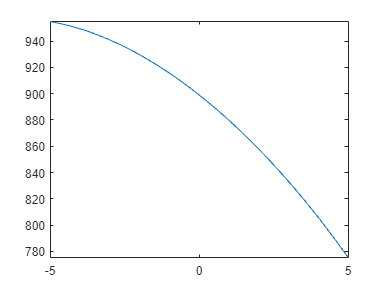

clear; close; clc;

% currently siteing TCDS and wikipedia

% performance characteristics
% W_operating_empty = 
% W_F_max = 
% W_cargo_max = 
W_MGTOW = 11431; % maxiumum gross takeoff weight (kg) 

Load_max = 1.1 * W_MGTOW;

% geometery
b = 29; % wingspan (m)

diagram_conversion_factor = (b/2) / 7.4; % convertsion from diagram to full scale (m/cm)

c_r = 2.8 * diagram_conversion_factor; % tip cord (m)
c_t = .7 * diagram_conversion_factor; % root cord (m)

syms y 
Load_elliptic = 4 * Load_max / (pi * b) * sqrt(1 - (2*y/b)^2);
Load_trapezoidal = 2 * Load_max / (b * (1 + c_t/c_r)) * (1 - (2*y/b)*(1-c_t/c_r));
Load = (Load_elliptic + Load_trapezoidal)/2;
fplot(@(y) ((4 * Load_max / (pi * b) * sqrt(1 - (2*y/b)^2)) + (2 * Load_max / (b * (1 + c_t/c_r)) * (1 - (2*y/b)*(1-c_t/c_r))) / 2));


nPoints = 1000 % increase this when all is working

nPoints = 1000

y = linspace(0, b/2, nPoints)

y =          0    0.0145    0.0290    0.0435    0.0581    0.0726    0.0871    0.1016    0.1161    0.1306    0.1451    0.1597    0.1742    0.1887    0.2032    0.2177    0.2322    0.2467    0.2613    0.2758    0.2903    0.3048    0.3193    0.3338    0.3483    0.3629    0.3774    0.3919    0.4064    0.4209    0.4354    0.4499    0.4645    0.4790    0.4935    0.5080    0.5225    0.5370    0.5516    0.5661    0.5806    0.5951    0.6096    0.6241    0.6386    0.6532    0.6677    0.6822    0.6967    0.7112


Lift = Schrenk_Lift_aproximation(y , b, c_r, c_t, Load_max)

Lift =   622.9035  622.6429  622.3821  622.1210  621.8596  621.5979  621.3360  621.0738  620.8113  620.5485  620.2855  620.0222  619.7586  619.4947  619.2306  618.9661  618.7014  618.4365  618.1712  617.9057  617.6399  617.3738  617.1074  616.8408  616.5739  616.3067  616.0392  615.7715  615.5034  615.2351  614.9666  614.6977  614.4286  614.1592  613.8895  613.6195  613.3493  613.0788  612.8080  612.5369  612.2655  611.9939  611.7220  611.4498  611.1774  610.9046  610.6316  610.3583  610.0848  609.8109


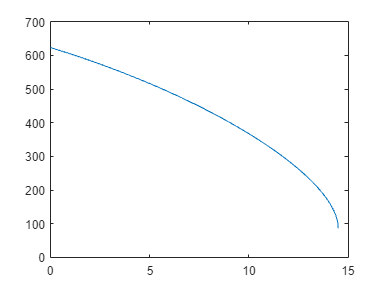

plot(y,Lift)


% NOTE FROM BARRETT INTEGRATE FROM TIP INBOARD NOT THE OTHER WAY

